close all
clear
clc

准备工作

[t,omg,FT,IFT] = prefourier([-1,1],500,[-25,25],500);
tau = 1;
E = 1;

生成矩形脉冲g和三角脉冲的时域波形

g = sqrt(2*E/tau)*(t>-tau/4&t<tau/4);
f = E*(1-2*abs(t)/tau).*(t>-tau/2&t<tau/2);

用傅里叶变换计算两者的频谱

G = FT*g;
F = FT*f;

直接绘出三角脉冲的波形（左子图）和频谱（右子图）

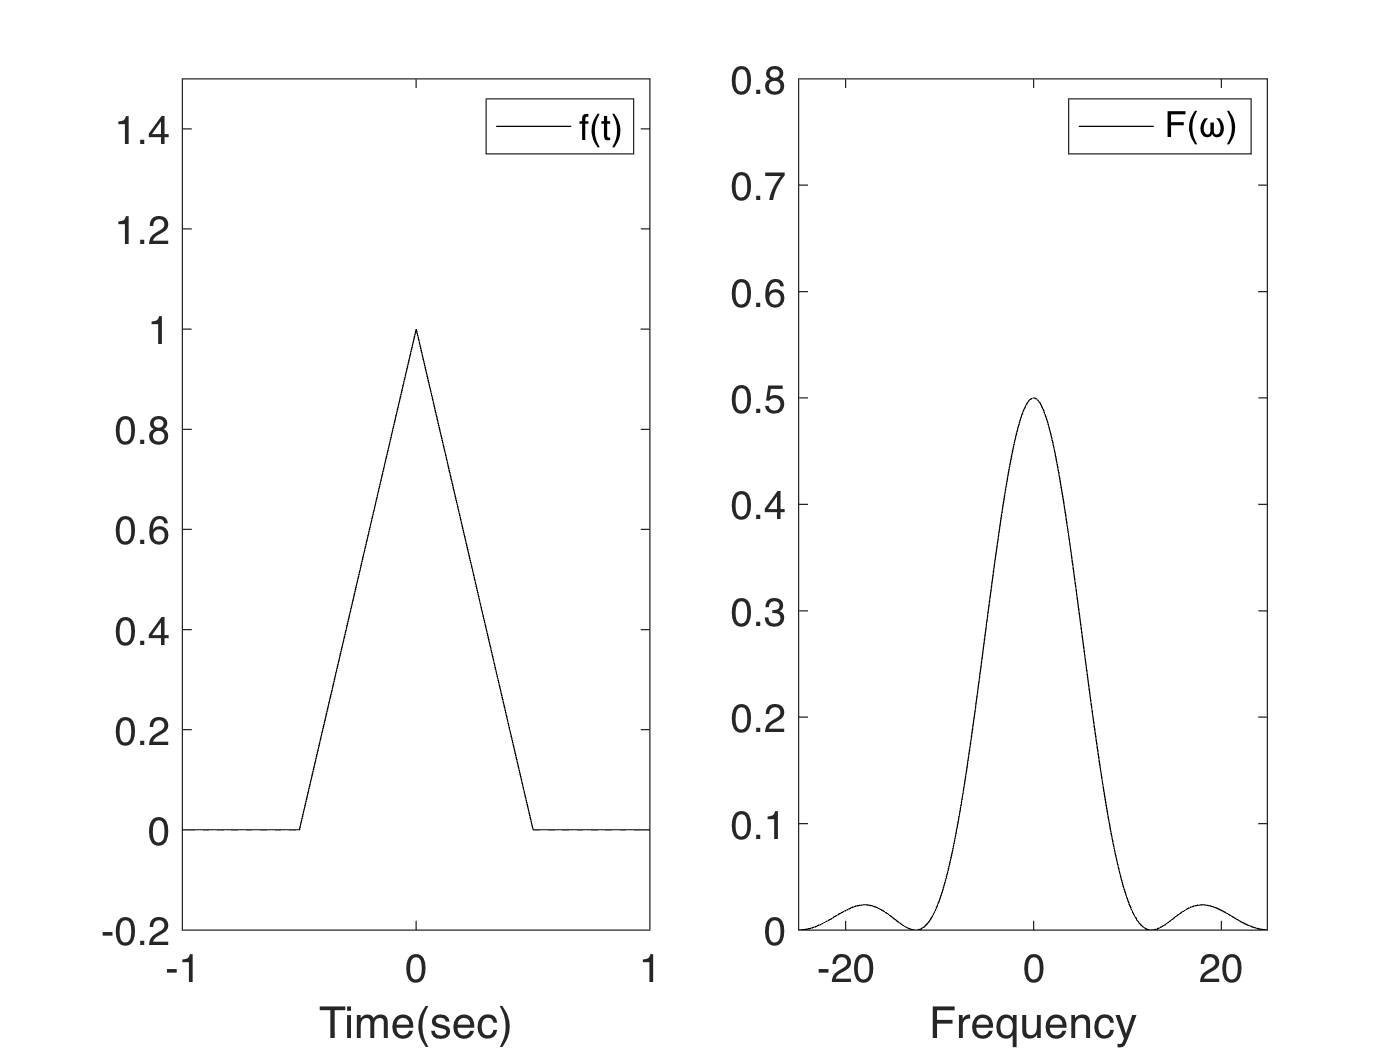

figure;
subplot(1,2,1), hold on, box on;
plot(t,f,'k-');
set(gca,'FontSize',16);
set(gca,'YLim',[-0.2,1.5]);
xlabel('Time(sec)');
legend('f(t)');
subplot(1,2,2), hold on, box on;
plot(omg,real(F),'k-');
set(gca,'FontSize',16);
set(gca,'YLim',[0,0.8]);
xlabel('Frequency');
legend('F(\omega)');

用矩形脉冲频谱的平方作为三角脉冲的频谱，再逆变换计算矩形脉冲的时域波形

Fe = G.*G;
fe = IFT*Fe;

绘出傅里叶变换算出的三角脉冲的波形（左子图）和频谱（右子图），并与矩形脉冲的波形和频谱对比

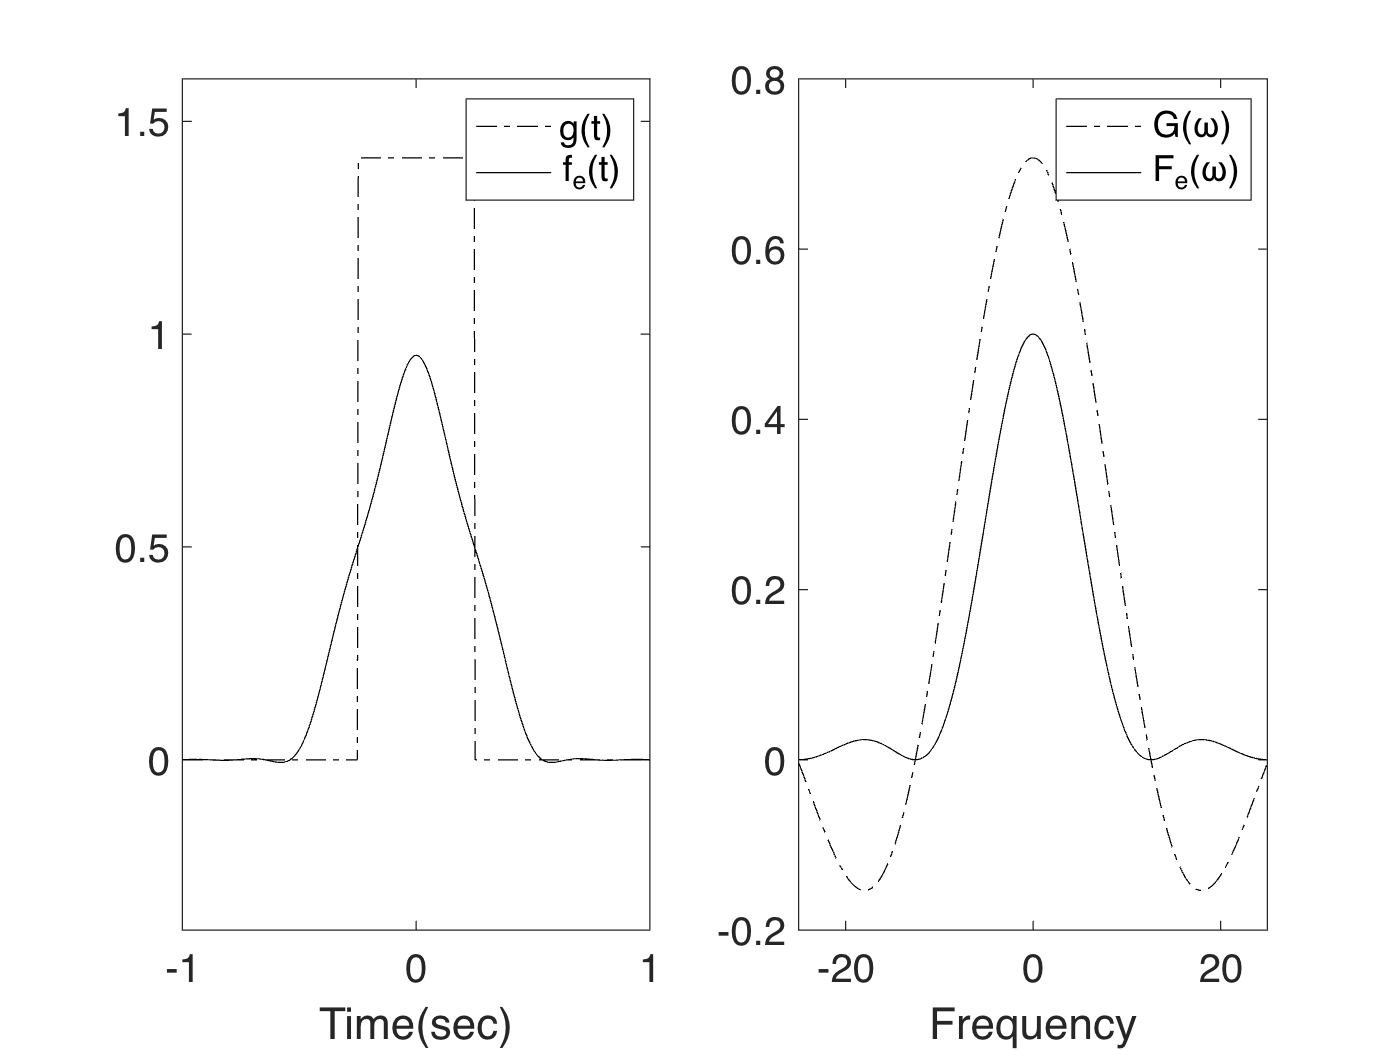

figure
subplot(1,2,1), hold on, box on;
plot(t,g,'k-.',t,real(fe),'k-');
set(gca,'FontSize',16);
set(gca,'YLim',[-0.2,0.8]*2);
xlabel('Time(sec)');
legend('g(t)','f_e(t)');
subplot(1,2,2), hold on, box on;
plot(omg,real(G),'k-.');
plot(omg,real(Fe),'k-');
set(gca,'FontSize',16);
set(gca,'YLim',[-0.2,0.8],'XLim',[-25,25]);
xlabel('Frequency');
legend('G(\omega)','F_e(\omega)');